# MATLAB 코드: Excel 데이터 파일 불러오기 및 산점도 플롯

% -------------------------------------------------------------------------
% 1. 데이터 불러오기
% -------------------------------------------------------------------------
clear; close all; clc;

% *** 사용자 설정: Excel 파일 이름을 실제 파일명으로 변경하세요. ***
file_path = 'Encoder.Data.xlsx'; 
% 예시: data_all = readmatrix('C:\Users\User\Documents\Encoder_Data_All.xlsx');

try
    % Excel 파일의 모든 데이터를 행렬로 불러옵니다.
    % 파일은 첫 번째 열(A열)에 각도(X), 두 번째 열(B열)에 값(Y)을 포함해야 합니다.
    data_all = readmatrix(file_path);
    
catch ME
    disp('*** 오류: Excel 파일을 불러올 수 없습니다. 파일 경로와 이름을 확인하세요. ***');
    rethrow(ME);
end

% -------------------------------------------------------------------------
% 2. 데이터 분리
% -------------------------------------------------------------------------

% 첫 번째 열을 X축 데이터 (각도)로 지정
x_angle = data_all(:, 1);

% 두 번째 열을 Y축 데이터 (인코더 값)로 지정
y_value = data_all(:, 2);

% -------------------------------------------------------------------------
% 3. 그래프 플롯
% -------------------------------------------------------------------------

figure;


disp(' ');

disp('---------------------------------------------------------');

---------------------------------------------------------


disp(['총 ' num2str(length(x_angle)) '개의 데이터 포인트가 플롯되었습니다.']);

총 234개의 데이터 포인트가 플롯되었습니다.


disp('---------------------------------------------------------');

---------------------------------------------------------



P = polyfit(x_angle,y_value, 1)

P =     3.0446  483.4231


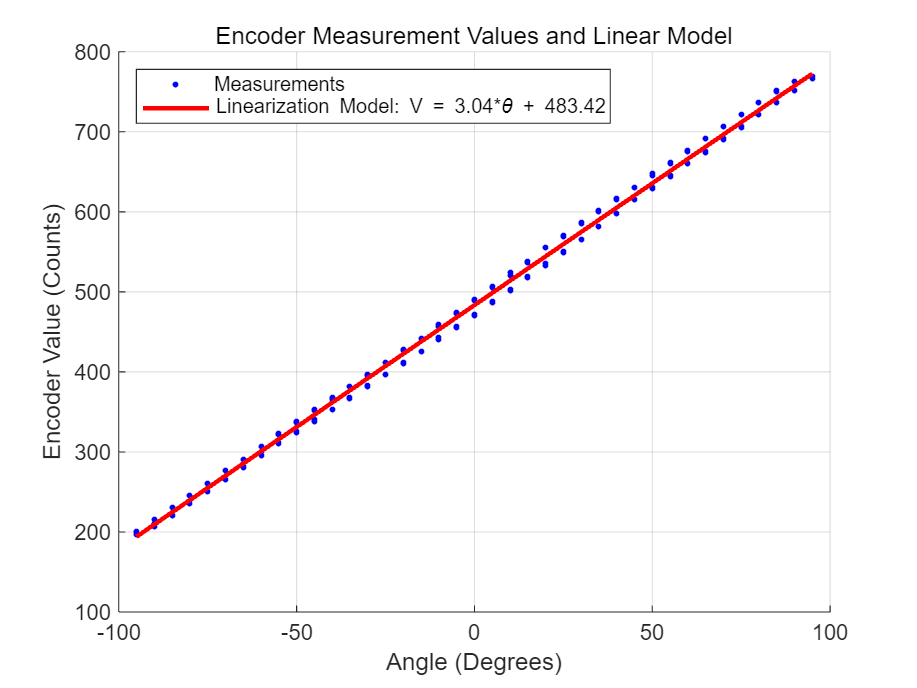

m = P(1); % 기울기 (Scale Factor: 1도당 인코더 카운트 변화량)
b = P(2); % y절편 (Offset)
y_linear= polyval(P,x_angle);

hold on;


% Scatter Plot (Measured Data)
plot(x_angle, y_value, 'b.', 'MarkerSize', 8, 'DisplayName', 'Measurements');


% Linearization Model
plot(x_angle, y_linear, 'r-', 'LineWidth', 2, ...
    'DisplayName', sprintf('Linearization Model: V = %.2f*\\theta + %.2f', m, b)); 


title('Encoder Measurement Values and Linear Model');
xlabel('Angle (Degrees)');
ylabel('Encoder Value (Counts)');
grid on;
legend('show', 'Location', 'NorthWest');
hold off;


mdl = fitlm(x_angle, y_value)

mdl = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                   Estimate       SE        tStat       pValue   
                   ________    _________    ______    ___________

    (Intercept)     483.42       0.51566    937.48              0
    x1              3.0446     0.0091635    332.25    1.0706e-312


관측값 개수: 234, 오차 자유도: 232
RMS 오차: 7.89
결정계수: 0.998, 수정된 결정계수: 0.998
상수 모델에 대한 F-통계량: 1.1e+05, p-값 = 1.07e-312